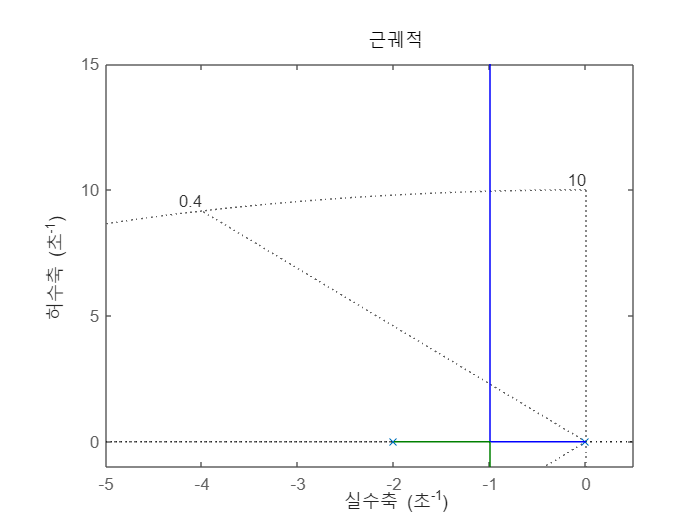

% Phase-lead compensator using root locus
% phase-lead compensator의 특징은 abs(z_0)<abs(p_0)
% steady-state error<5% -> Kv>20, damping ratio >= 0.4, wn=10

s = tf('s');
G = 40/(s*(s+2));

zeta = 0.4;
w_n = 10;
rlocus(G);
axis([-5, 0.5, -1, 15])
sgrid(zeta, w_n)

z_0 = -zeta*w_n

z_0 = -4

desired_root = z_0 + 1i*sqrt(w_n^2-z_0^2) % 피타고라스

desired_root = -4.0000 + 9.1652i

angle_p_0 = pi-(sum(angle(desired_root-pole(G)))-angle(desired_root-z_0)) % 180deg-((desired root's deg - poles' deg) - (desired root's deg - zeros' deg))

angle_p_0 = 0.9444

p_0 = z_0 - sqrt(w_n^2-z_0^2) / tan(angle_p_0) % 직각삼각형을 이용하여 zero(-4,0) - p_0의 x좌표

p_0 = -10.6316

C_lead = (s-z_0)/(s-p_0)

C_lead =
 
    s + 4
  ---------
  s + 10.63
 
연속시간 전달 함수입니다.
모델 속성


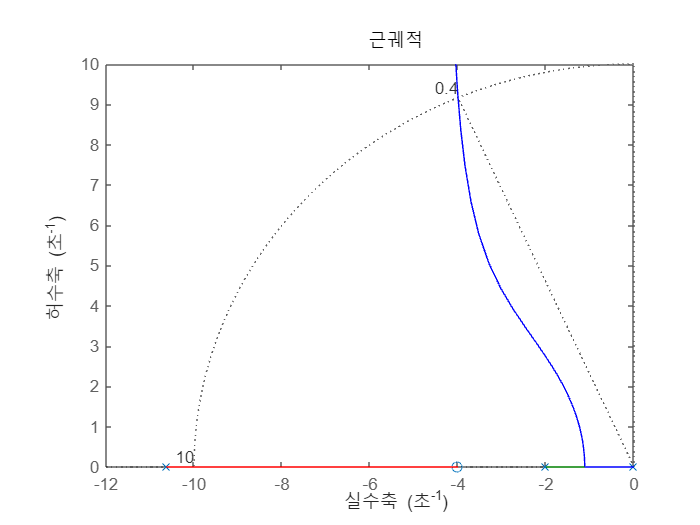

rlocus(C_lead*G);
axis([-12, 0, 0, 10]);
sgrid(zeta,w_n);

K = rlocfind(C_lead*G, desired_root) % K값 찾는 코드rlocfind(sys, pole)

K = 2.8947

C_lead = C_lead*K

C_lead =
 
  2.895 s + 11.58
  ---------------
     s + 10.63
 
연속시간 전달 함수입니다.
모델 속성


Kv = dcgain(G*C_lead*s) % dc일 때의 gain, 즉 주파수가 0일 때의 gain / Kv는 s가 0으로 수렴할 때의 gain

Kv = 21.7822

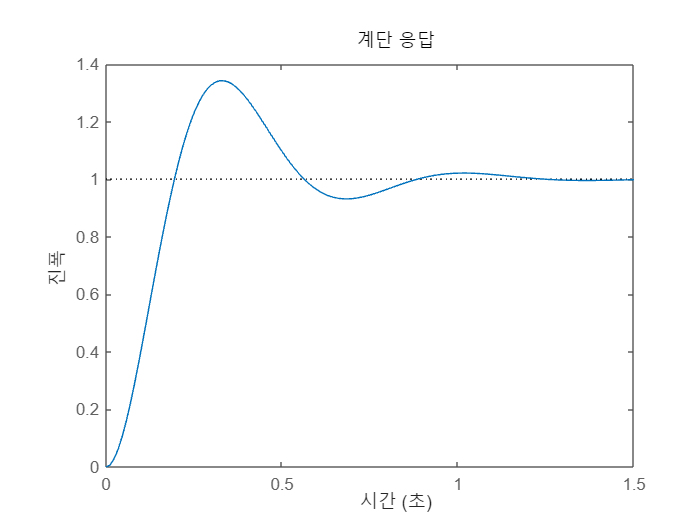

sys_cl = feedback(G*C_lead, 1);
step(sys_cl)

stepinfo(sys_cl)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.1319
    TransientTime: 1.0522
     SettlingTime: 1.0522
      SettlingMin: 0.9314
      SettlingMax: 1.3420
        Overshoot: 34.1970
       Undershoot: 0
             Peak: 1.3420
         PeakTime: 0.3339


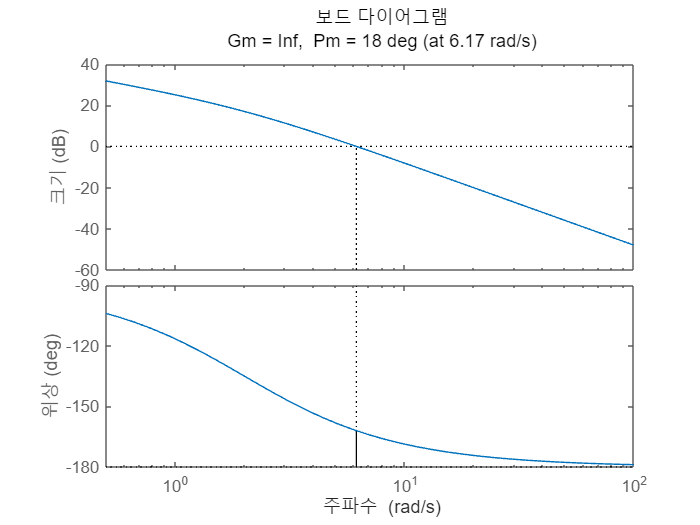

% Phase-lead compensator using frequency response
clear;

s = tf('s');
G = 40/(s*(s+2));
margin(G);
axis([0.5, 100, -180, -90])

[Gm, Pm, Wg, Wp] = margin(G)

Gm = Inf

Pm = 17.9642

Wg = Inf

Wp = 6.1685

desired_Pm = 40;
required_Pm = desired_Pm - Pm + 8 % 8은 여윳값

required_Pm = 30.0358


syms a
a = double(solve(sin(deg2rad(required_Pm))==(a-1)/(a+1))) % sin(phi) = (a-1)/(a+1) 방정식을 푼 것

a = 3.0043

C_gain_center = sqrt(a);
wm = getGainCrossover(G, 1/C_gain_center)

wm = 8.2074

z_0 = -wm/sqrt(a)

z_0 = -4.7351

p_0 = a*z_0 % a = z_0/p_0

p_0 = -14.2258

C_lead = (s-z_0)/(s-p_0);
Kv = dcgain(s*C_lead*G)

Kv = 6.6571

C_lead = C_lead * 20/Kv

C_lead =
 
   20 s + 94.7
  --------------
  6.657 s + 94.7
 
연속시간 전달 함수입니다.
모델 속성


Kv = dcgain(s*C_lead*G) % Kv가 Kv>20이라는 조건보다 부족하므로 20이 되도록 맞춤

Kv = 20

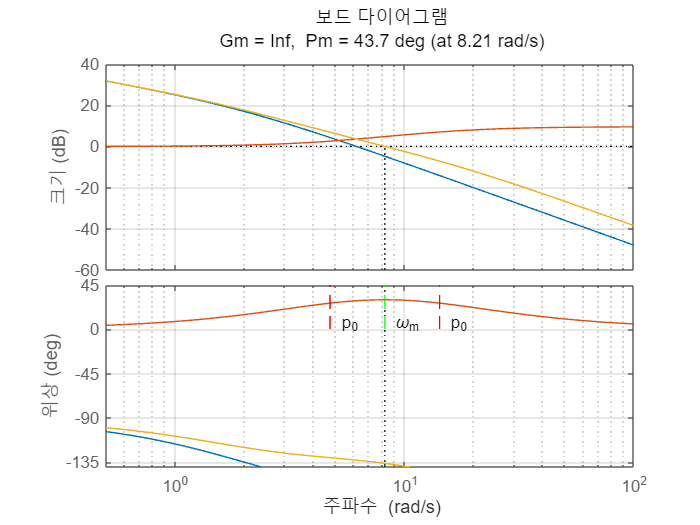

bode(G, C_lead);
grid on
axis([0.5, 100, -140, 45])
hold on;
margin(G*C_lead); % 노란선이 margin plot, 주황색이 compensator
plot([-z_0, -z_0],[0, 90], 'r--');
text(-z_0*1.1,5,'p_0');
plot([-p_0, -p_0], [0, 90], 'r--');
text(-p_0*1.1, 5, 'p_0');
plot([wm wm], [0, 90], 'g--');
text(wm*1.1, 5, '\omega_m');
hold off

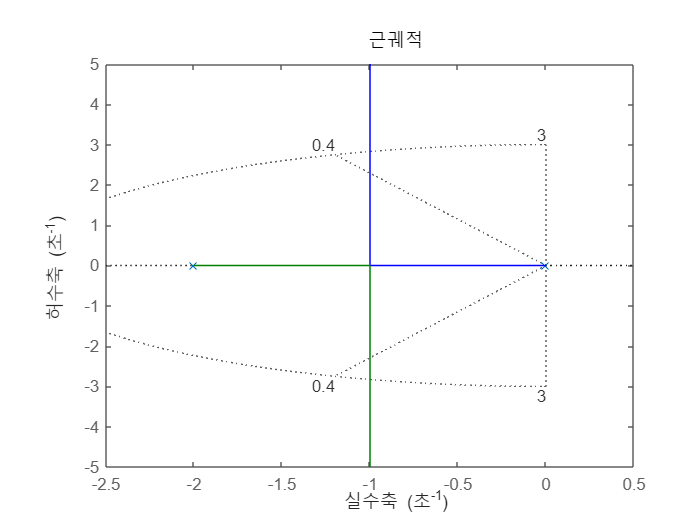

% Phase-lag compensator using root locus
clear;

s = tf('s');
G = 40/(s*(s+2));
Kv_desired = 20;
zeta = 0.4;
rlocus(G);
axis([-2.5, 0.5, -5, 5]);
sgrid(zeta, 3);


root_real = -1;
theta = acos(zeta); % zeta = cos(theta)
root_angle = pi-theta;
root_imag = 1i*root_real*tan(root_angle);
root = root_real + root_imag

root = -1.0000 + 2.2913i

K = rlocfind(G, root)

K = 0.1562


Kv = dcgain(s*K*G)

Kv = 3.1250

alpha = Kv_desired / Kv

alpha = 6.4000

z_0 = -0.1, p_0 = -0.1/alpha % alpha = z_0/p_0, z_0는 책에 나온대로 -0.1로 셋팅함

z_0 = -0.1000

p_0 = -0.0156


C_lag = K * (s-z_0) / (s-p_0)

C_lag =
 
  0.1562 s + 0.01562
  ------------------
     s + 0.01562
 
연속시간 전달 함수입니다.
모델 속성


sys_cl = feedback(C_lag*G, 1)

sys_cl =
 
           6.25 s + 0.625
  ---------------------------------
  s^3 + 2.016 s^2 + 6.281 s + 0.625
 
연속시간 전달 함수입니다.
모델 속성


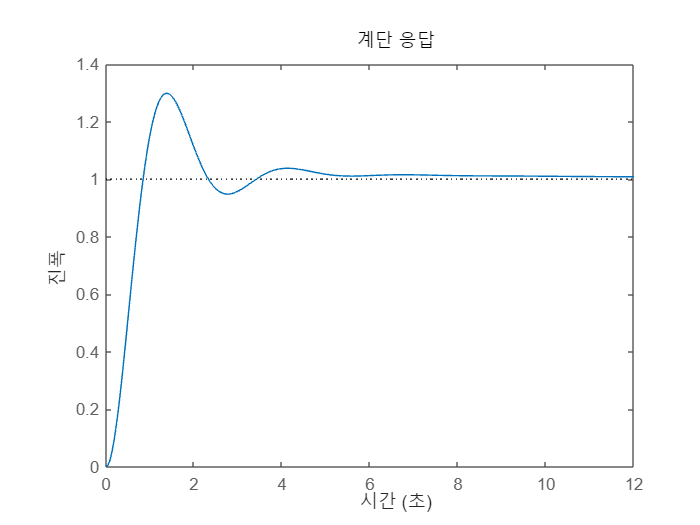

step(sys_cl)

stepinfo(sys_cl)

ans = 다음 필드를 포함한 struct :
         RiseTime: 0.5704
    TransientTime: 4.8815
     SettlingTime: 4.8815
      SettlingMin: 0.9114
      SettlingMax: 1.2983
        Overshoot: 29.8285
       Undershoot: 0
             Peak: 1.2983
         PeakTime: 1.3963


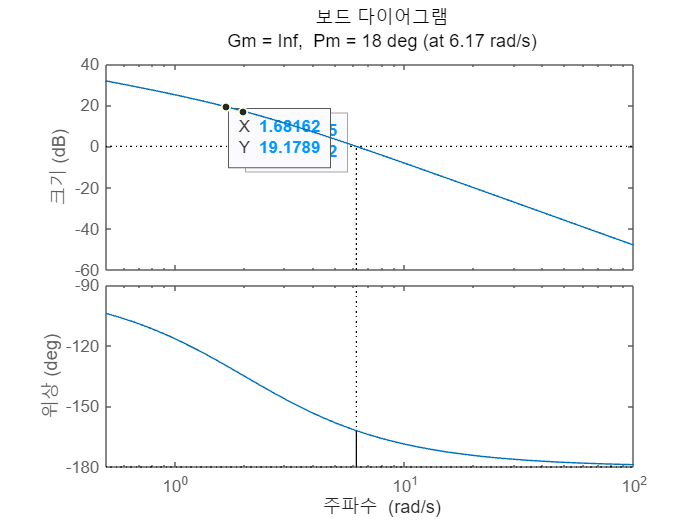

% Phase-lag compensator using frequency response
clear;

s = tf('s');
G = 40/(s*(s+2));
margin(G)
axis([0.5, 100, -180, -90])


desired_Pm = 50; % 즉, -130deg일 때 mag가 0dB이어야 하므로 phase plot에서 -130deg일 때의 주파수를 찾고 그때의 mag를 0dB로 만들어야 함
[mag1, phase1, omega1] = bode(G,{1,6});
omega1

omega1 =     1.0000
    1.0595
    1.1225
    1.1893
    1.2601
    1.3351
    1.4145
    1.4987
    1.5879
    1.6823


squeeze(phase1)

ans =  -116.5651
 -117.9124
 -119.3043
 -120.7386
 -122.2131
 -123.7248
 -125.2703
 -126.8459
 -128.4472
 -130.0696


[min_val, idx] = min(abs(squeeze(phase1)+130))

min_val = 0.0696

idx = 10

omega1(idx)

ans = 1.6823

w_c = omega1(idx) % -130deg일 때의 주파수는 찾았다고 가정

w_c = 1.6823

[mag, phase] = bode(G, w_c)

mag = 9.0976

phase = -130.0696


alpha = mag;  
z_0 = -w_c/10, p_0 = z_0/alpha, K = 1/alpha

z_0 = -0.1682

p_0 = -0.0185

K = 0.1099


C_lag = K * (s-z_0) / (s-p_0)

C_lag =
 
  0.1099 s + 0.01849
  ------------------
     s + 0.01849
 
연속시간 전달 함수입니다.
모델 속성


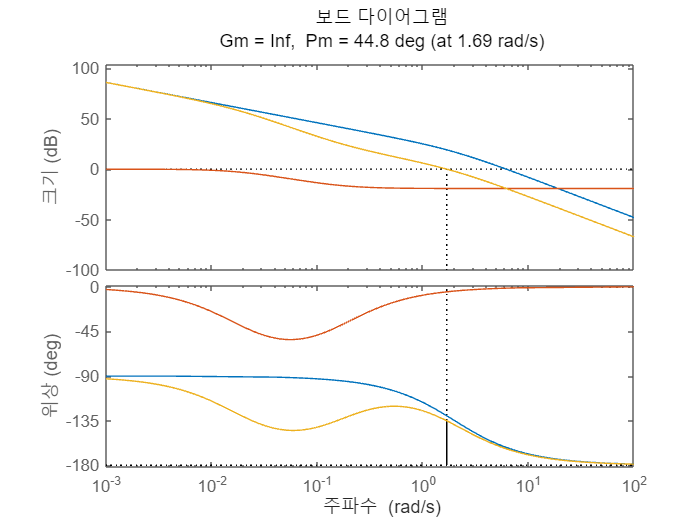


bode(G)
hold on
bode(C_lag)
margin(G*C_lag) % 노란색이 margin(phase-lag) plot, 주황색이 compensator
hold off